dt=1/1000;
t = 0:dt:0.5;
u1 = sin(2*pi*50*t);
u2 = sin(2*pi*100*t);
u3 = 0*sin(2*pi*75*t);

u = u1+u2+u3;
M=300;
H = hankel(u(1:M),u(M:end));

[U,S,V]=svd(H);

rr=rank(H)

rr = 4

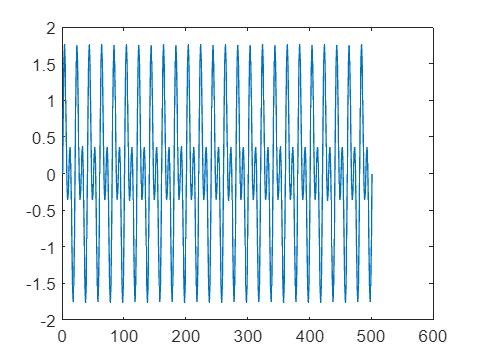

figure; plot(u)

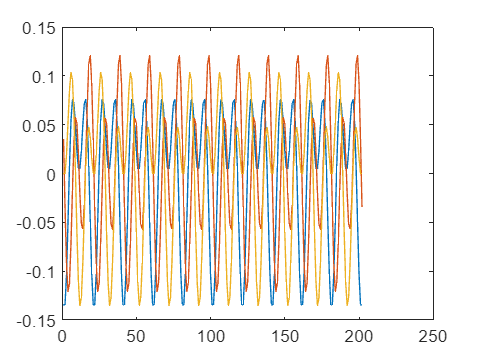

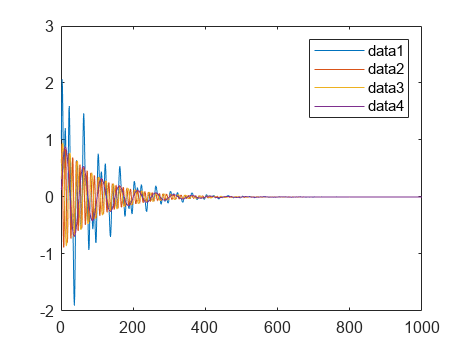

hankelSeries =     1.0120    1.7521    2.0653    1.9414    1.5103    0.9868    0.5860    0.4441    0.5722    0.8606    1.1297    1.2074    1.0011    0.5381   -0.0421   -0.5403   -0.7726   -0.6418   -0.1755    0.4812    1.1174    1.5304    1.5960    1.3091    0.7788    0.1835   -0.2983   -0.5528   -0.5691   -0.4354   -0.2976   -0.2957   -0.5049   -0.9026   -1.3749   -1.7589   -1.9051   -1.7349   -1.2723   -0.6375   -0.0053    0.4563    0.6437    0.5502    0.2628   -0.0748   -0.3189   -0.3787   -0.2476    0.0000
    1.7521    2.0653    1.9414    1.5103    0.9868    0.5860    0.4441    0.5722    0.8606    1.1297    1.2074    1.0011    0.5381   -0.0421   -0.5403   -0.7726   -0.6418   -0.1755    0.4812    1.1174    1.5304    1.5960    1.3091    0.7788    0.1835   -0.2983   -0.5528   -0.5691   -0.4354   -0.2976   -0.2957   -0.5049   -0.9026   -1.3749   -1.7589   -1.9051   -1.7349   -1.2723   -0.6375   -0.0053    0.4563    0.6437    0.5502    0.2628   -0.0748   -0.3189   -0.3787   -0.2476    

ar_model =
Discrete-time AR model: A(z)y(t) = e(t)                                                                            
  A(z) = 1 - 7.126 z^-1 + 22.99 z^-2 - 43.79 z^-3 + 53.84 z^-4 - 43.75 z^-5 + 22.95 z^-6 - 7.107 z^-7 + 0.9965 z^-8
                                                                                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=8
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                          
Estimated using AR ('fb/now') on time domain data "train_series".
Fit to estimation data: 100%                                     
FPE: 5.668e-11, MSE: 5.578e-11                                   
 


    "Prediction using full time series (no noise): -9.5476e-05"
    "Prediction using full time series (no noise): -9.9543e-05"
    "Prediction using full time series (no noise): -8.2706e-05"
    "Prediction using full time series (no noise): -4.6597e-05"
    "Prediction using full time series (no noise): 6.8875e-07"



    "Ground truth: -9.5479e-05"
    "Ground truth: -9.9563e-05"
    "Ground truth: -8.2793e-05"
    "Ground truth: -4.6871e-05"
    "Ground truth: 6.9033e-19"



ans =      7



%kunnen we dmv de values van V en die individueel gebruiken om het volgende
%punt te voorspelen mogelijk een betere voorspelling doen dan als we het
%gecombineerde gebruiken om het volgende punt te voorspellen?
figure; plot(V(:,1));
hold all; plot(V(:,2));
plot(V(:,3))

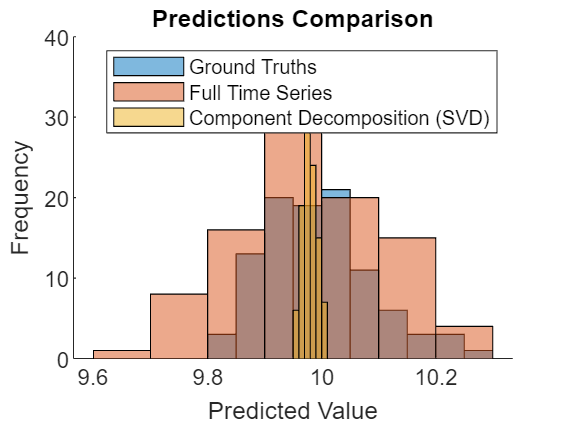

figure;
hold on;
histogram(ground_truths, 'FaceAlpha', 0.5, 'DisplayName', 'Ground Truths');
histogram(predictions_full, 'FaceAlpha', 0.5, 'DisplayName', 'Full Time Series');
histogram(predictions_SVD, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (SVD)');
title('Predictions Comparison');
xlabel('Predicted Value');
ylabel('Frequency');
legend;
hold off;

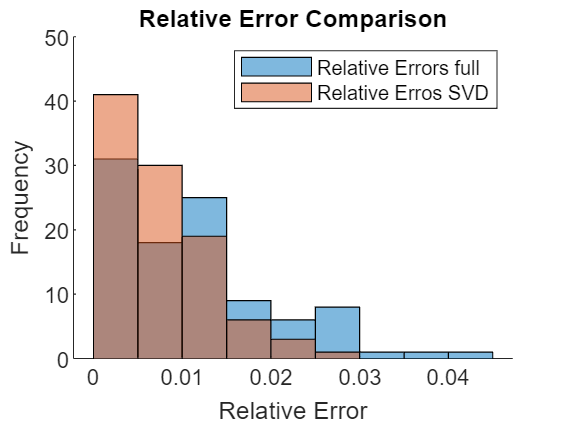


figure;
hold on;
histogram(rel_error_full, 'FaceAlpha', 0.5, 'DisplayName', 'Relative Errors full');
histogram(rel_error_SVD, 'FaceAlpha', 0.5, 'DisplayName', 'Relative Erros SVD');
%histogram(predictions_SVD, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (SVD)');
title('Relative Error Comparison');
xlabel('Relative Error');
ylabel('Frequency');
legend;
hold off;

## Full AR, SVD, CPD, MLSVD

First we create the time-series signal

clear all;
format long;
addpath('./tensorlab/');

% Parameters
N = 100;  % Number of points in the time series
num_predict = 1;
optimal_order = 10;  % Set a fixed optimal order for simplicity for AR

% Generate sinusoidal signals
t = (1:N)';

% Determine option testing purposes
signal_option = 3;
noise_option = 1;

% Signal multiplicator
smul = 40*rand();

% Define base signals without decay and random addition
base_signal1 = smul*sin(2 * pi  * 0.1 * t);
base_signal2 = smul*sin(2 * pi  * 0.05 * t);
base_signal3 = smul*sin(2 * pi  * 0.02 * t);

% Apply selected option
switch signal_option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    case 4
        % No decay, random addition
        signal1 = base_signal1 + rand() * 10;
        signal2 = base_signal2 - rand() * 10;
        signal3 = base_signal3 + rand() * 10;
    otherwise
        error('Invalid option selected');
end

% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Plot the time series
figure;
plot(time_series);
hold on;
%plot(noisy_series);
legend({"Original", "Gaussian Noise"})
hold off;
title('Time Series');
xlabel('Time');
ylabel('Value');

Now we simulate the forecasting methods

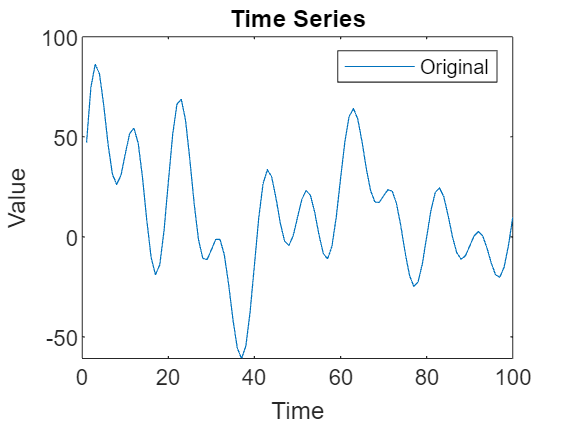

num_experiments = 100;  % Number of experiments to perform
num_components = 7; % For SVD and CPD


% Ground truth for final point
ground_truths = zeros(num_predict, num_experiments);

% Prepare storage for predictions
predictions_full = zeros(num_predict, num_experiments);
rel_error_full = zeros(num_predict, num_experiments);
norm_error_full = zeros(num_predict, num_experiments);

predictions_SVD = zeros(num_predict, num_experiments);
rel_error_SVD = zeros(num_predict, num_experiments);
norm_error_SVD = zeros(num_predict, num_experiments);

predictions_CPD = zeros(num_predict, num_experiments);
rel_error_CPD = zeros(num_predict, num_experiments);
norm_error_CPD = zeros(num_predict, num_experiments);

predictions_mlsvd = zeros(num_predict, num_experiments);
rel_error_mlsvd = zeros(num_predict, num_experiments);
norm_error_mlsvd = zeros(num_predict, num_experiments);

predictions_cpd_col = zeros(num_predict, num_experiments);
rel_error_cpd_col = zeros(num_predict, num_experiments);
norm_error_cpd_col = zeros(num_predict, num_experiments);

% Perform the experiment
for exp = 1:num_experiments 
    if mod(exp,1)==0
        disp("iter "+exp);
    end
    
    %ground_truths(:,exp) = time_series(end-num_predict+1:end); 
    
    noisy_series = time_series + noise_option*(randn(N, 1) * 0.4);
    ground_truths(:,exp) = noisy_series(end-num_predict+1:end);

    training_series = noisy_series(1:end-num_predict);
    
    % 1. Full time series prediction using AR model
    model_full = ar(training_series, optimal_order);  % AR(optimal_order) model
    predictions_full(:,exp) = forecast(model_full, training_series, num_predict);

    % 2. Decomposition using Hankel Matrix (SVD)
    predictions_SVD(:,exp) = ar_svd(training_series,num_predict,optimal_order,num_components);

    % 3. Decomposition using Hankel Tensor (CPD sum of mean anti-diagonals)
    predictions_CPD(:,exp) = ar_cpd_ms(training_series,num_predict,optimal_order,num_components);

    % 4. Decomposition using Hankel Tensor (CPD predict along column c)
    predictions_cpd_col(:,exp) = ar_cpd_col(training_series,num_predict,10,num_components);

    % 5. Decomposition using Hankel Tensor (MLSVD)
    predictions_mlsvd(:,exp) = ar_mlsvd(training_series,num_predict,optimal_order,0.2);

    % 6. Error calculations
    rel_error_full(:,exp) = abs(predictions_full(:,exp)-ground_truths(:,exp))./abs(ground_truths(:,exp));
    norm_error_full(:,exp) = norm(predictions_full(:,exp),2)./norm(ground_truths(:,exp),2);

    rel_error_SVD(:,exp) = abs(predictions_SVD(:,exp)-ground_truths(:,exp))./abs(ground_truths(:,exp));
    norm_error_SVD(:,exp) = norm(predictions_SVD(:,exp),2)./norm(ground_truths(:,exp),2);

    rel_error_CPD(:,exp) = abs(predictions_CPD(:,exp)-ground_truths(:,exp))./abs(ground_truths(:,exp));
    norm_error_CPD(:,exp) = norm(predictions_CPD(:,exp),2)./norm(ground_truths(:,exp),2);

    rel_error_cpd_col(:,exp) = abs(predictions_cpd_col(:,exp)-ground_truths(:,exp))./abs(ground_truths(:,exp));
    norm_error_cpd_col(:,exp) = norm(predictions_cpd_col(:,exp),2)./norm(ground_truths(:,exp),2);
   
    rel_error_mlsvd(:,exp) = abs(predictions_mlsvd(:,exp)-ground_truths(:,exp))./abs(ground_truths(:,exp));
    norm_error_mlsvd(:,exp) = norm(predictions_mlsvd(:,exp),2)./norm(ground_truths(:,exp),2);
end
disp("Done!");

% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');
disp("Mean: "+mean(predictions_full,2)+ ...
    ", SD: "+std(predictions_full,0,2)+ ...

iter 1
iter 2
iter 3
iter 4
iter 5
iter 6
iter 7
iter 8
iter 9
iter 10
iter 11
iter 12
iter 13
iter 14
iter 15
iter 16
iter 17
iter 18
iter 19
iter 20
iter 21
iter 22
iter 23
iter 24
iter 25
iter 26
iter 27
iter 28
iter 29
iter 30
iter 31
iter 32
iter 33
iter 34
iter 35
iter 36
iter 37
iter 38
iter 39
iter 40
iter 41
iter 42
iter 43
iter 44
iter 45
iter 46
iter 47
iter 48
iter 49
iter 50
iter 51
iter 52
iter 53
iter 54
iter 55
iter 56
iter 57
iter 58
iter 59
iter 60
iter 61
iter 62
iter 63
iter 64
iter 65
iter 66
iter 67
iter 68
iter 69
iter 70
iter 71
iter 72
iter 73
iter 74
iter 75
iter 76
iter 77
iter 78
iter 79
iter 80
iter 81
iter 82
iter 83
iter 84
iter 85
iter 86
iter 87
iter 88
iter 89
iter 90
iter 91
iter 92
iter 93
iter 94
iter 95
iter 96
iter 97
iter 98
iter 99
iter 100


    ", RMSE: "+rmse(predictions_full,ground_truths,2)+ ...

Done!


    ", MRE: "+mean(rel_error_full,2)+ ...
    ", MRSE: "+mean(norm_error_full,2));


Full Time Series Predictions:


errors_full = [mean(predictions_full,2),std(predictions_full,0,2),rmse(predictions_full,ground_truths,2),mean(rel_error_full,2),mean(norm_error_full,2)]';

disp('Component Decomposition Predictions (SVD):');
disp("Mean: "+mean(predictions_SVD,2)+ ...
    ", SD: "+std(predictions_SVD,0,2)+ ...

Mean: 8.9754, SD: 1.038, RMSE: 1.2535, MRE: 0.10345, MRSE: 0.92814


    ", RMSE: "+rmse(predictions_SVD,ground_truths,2)+ ...
    ", MRE: "+mean(rel_error_SVD,2)+ ...
    ", MRSE: "+mean(norm_error_SVD,2));


Component Decomposition Predictions (SVD):


errors_SVD = [mean(predictions_SVD,2),std(predictions_SVD,0,2),rmse(predictions_SVD,ground_truths,2),mean(rel_error_SVD,2),mean(norm_error_SVD,2)]';


disp('Component Decomposition Predictions (CPD_ms):');
disp("Mean: "+mean(predictions_CPD,2)+ ...

Mean: 9.766, SD: 0.23996, RMSE: 0.46775, MRE: 0.039552, MRSE: 1.0108


    ", SD: "+std(predictions_CPD,0,2)+ ...
    ", RMSE: "+rmse(predictions_CPD,ground_truths,2)+ ...
    ", MRE: "+mean(rel_error_CPD,2)+ ...
    ", MRSE: "+mean(norm_error_CPD,2));


Component Decomposition Predictions (CPD_ms):


errors_CPD = [mean(predictions_CPD,2),std(predictions_CPD,0,2),rmse(predictions_CPD,ground_truths,2),mean(rel_error_CPD,2),mean(norm_error_CPD,2)]';

disp('Component Decomposition Predictions (CPD_col):');
disp("Mean: "+mean(predictions_cpd_col,2)+ ...
    ", SD: "+std(predictions_cpd_col,0,2)+ ...

Mean: -21.1037, SD: 5.7009, RMSE: 31.3028, MRE: 3.1848, MRSE: 2.1848


    ", RMSE: "+rmse(predictions_cpd_col,ground_truths,2)+ ...
    ", MRE: "+mean(rel_error_cpd_col,2)+ ...
    ", MRSE: "+mean(norm_error_cpd_col,2));


Component Decomposition Predictions (CPD_col):


errors_cpd_col = [mean(predictions_cpd_col,2),std(predictions_cpd_col,0,2),rmse(predictions_cpd_col,ground_truths,2),mean(rel_error_cpd_col,2),mean(norm_error_cpd_col,2)]';

disp('Component Decomposition Predictions (MLSVD):');
disp("Mean: "+mean(predictions_mlsvd,2)+ ...
    ", SD: "+std(predictions_mlsvd,0,2)+ ...

Mean: -16.4305, SD: 5.8282, RMSE: 26.7481, MRE: 2.7011, MRSE: 1.7544


    ", RMSE: "+rmse(predictions_mlsvd,ground_truths,2)+ ...
    ", MRE: "+mean(rel_error_mlsvd,2)+ ...
    ", MRSE: "+mean(norm_error_mlsvd,2));


Component Decomposition Predictions (MLSVD):


errors_MLSVD = [mean(predictions_mlsvd,2),std(predictions_mlsvd,0,2),rmse(predictions_mlsvd,ground_truths,2),mean(rel_error_mlsvd,2),mean(norm_error_mlsvd,2)]';



Mean: 9.7625, SD: 0.45451, RMSE: 0.62714, MRE: 0.053677, MRSE: 1.0106


Next part is for concatenating the values

actual_stats = [mean(ground_truths,2),std(ground_truths,0,2),0,0,0]'
errors_concat1 = [actual_stats, errors_full, errors_SVD, errors_CPD, errors_cpd_col, errors_MLSVD];

actual_stats =    9.678601394535049
   0.420163244942369
                   0
                   0
                   0
